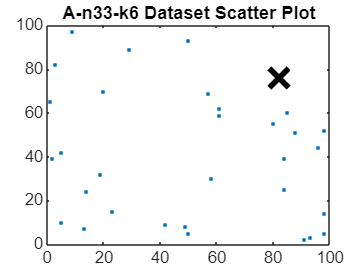

clc; clear; rng default;

instance = xlsread('A-n32-k5');
X = instance(2:end,2:3);
depot = instance(1,:);

figure;
plot(X(:,1),X(:,2),'.'); hold on;
plot(depot(2),depot(3),'kx','MarkerSize',15,'LineWidth',3);
title('A-n33-k6 Dataset Scatter Plot');

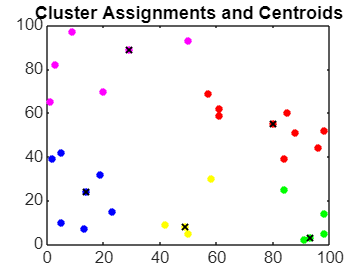


% Clustering with k-medoids
[idx, C] = kmedoids(X,5,'distance','seuclidean','replicates',1000);

% Cluster visualization
colors = {'r.','b.','y.','m.','g.'};
figure;
for k = 1:5
    plot(X(idx==k,1),X(idx==k,2),colors{k},'MarkerSize',12); hold on;
end
plot(C(:,1),C(:,2),'kx','MarkerSize',5,'LineWidth',1);
title('Cluster Assignments and Centroids'); hold off;


% Combine clusters
after_cluster = X;
after_cluster_node = cell2mat(arrayfun(@(i) find(ismember(X, after_cluster(i,:),'rows'))+1, 1:length(after_cluster), 'UniformOutput', false));
after_cluster_node = [1; after_cluster_node'];

% Evaluate initial solution
truck_capacity = 100;
[fitness_cluster,route_sequence] = Obj_function_VRP_v3(instance,after_cluster_node,truck_capacity);

RouteVRP_v3 is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\lmaos\OneDrive\Documents\Tugas\Smt 2\TDOSM\UTS\MATLAB\Akhdan
    C:\Users\lmaos\OneDrive\Documents\JPN\KULYEAH\Thesis\drnt\MATLAB_DRIVE\Akhdan

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in Obj_function_VRP_v3 (line 2)
[route_sequence,depot_vrp,instance_without_depot] = RouteVRP_v3(instance,node_shuffle,truck_capacity);


% Initial Population
number_pop = 500;
Pop = zeros(number_pop, length(instance));
for n = 1:number_pop
    Pop(n,:) = randperm(length(instance));
end

% Evaluate cost
cost = zeros(number_pop,1);
for i = 1:number_pop
    cost(i) = Obj_function_VRP_v3(instance,Pop(i,:),truck_capacity);
end

% Seed best known solution
for n = 1:round(0.1*number_pop)
    Pop(n,:) = after_cluster_node;
    cost(n,:) = fitness_cluster;
end

% GA Parameters
pbest = Pop;
f_pbest = cost;
[f_gbest,ind_f] = min(f_pbest);
gbest = pbest(ind_f,:);
BestFitIter(1) = f_gbest;

% Hybrid GA + Local Search
LocalIter = 1200;
MaxIter = 100;
PerMut = 5; % Mutation probability
S = 2;      % Tournament size

for Gen = 1:MaxIter
    % Evaluate population
    for i = 1:number_pop
        cost(i) = Obj_function_VRP_v3(instance,Pop(i,:),truck_capacity);
    end

    % Tournament selection
    T = round(rand(2*number_pop,S)*(number_pop-1)+1);
    [~,idx] = min(cost(T),[],2);
    W = T(sub2ind(size(T),(1:2*number_pop)',idx));

    % Crossover
    P1 = Pop(W(1:2:end),:);
    P2 = Pop(W(2:2:end),:);
    cp = round(rand(number_pop,1)*(length(instance)-1)+1);
    for i = 1:number_pop
        temp = P2(i,cp(i):end);
        remain = setdiff(P1(i,:), temp, 'stable');
        Pop(i,:) = [remain temp];
    end

    % Mutation
    idx = rand(number_pop,1) < PerMut;
    for i = find(idx)'
        [a,b] = deal(randi(length(instance)), randi(length(instance)));
        Pop(i,[a b]) = Pop(i,[b a]);
    end

    % Local search on best
    for j = 1:LocalIter
        new_route = mutation_6(gbest,length(instance));
        [new_route_cost, ~] = Obj_function_VRP_v3(instance,new_route,truck_capacity);
        if new_route_cost <= f_gbest
            f_gbest = new_route_cost;
            gbest = new_route;
        end
    end

    BestFitIter(Gen) = f_gbest;
    disp(['Gen ' num2str(Gen) ' | Best Fitness: ' num2str(f_gbest)]);
end

% Final route display
[~,gbest_route_sequence] = Obj_function_VRP_v3(instance,gbest,truck_capacity);
for g = 1:length(gbest_route_sequence)
    disp(['Vehicle Route ' num2str(g) ': ' num2str(cell2mat(gbest_route_sequence{1,g}))]);
end

figure;
plot(1:MaxIter, BestFitIter);
xlabel('Generation'); ylabel('Best Fitness');
title('Convergence of Hybrid GA');